% Frenet frame calculations for robot path, used for engraving of phone
% ROB2 B225 AAU 2021

clc

syms s t theta

% Setup larger plots
%set(gcf, 'units', 'normalized');
%set(gcf, 'Position', [0, 0.1, 1, 0.9]);

% Definition of parametric surface
% Consider the Z-axis of this curve, where the color is bright yellow. (height)


$$r\left(s,t\right)=\left(x\left(s,\;t\right),y\left(s,\;t\right),z\left(s,\;t\right)\right)$$


x_st = s;
y_st = t;
z_st = -s^2+15.5;
%x_st = 152.41*cos(s);
%y_st = -137.29+152.41*sin(s);
%z_st = t;
r_st = [x_st, y_st, z_st]

$$r\_st = \left(\begin{array}{ccc} s & t & \frac{31}{2}-s^{2} \end{array}\right)$$

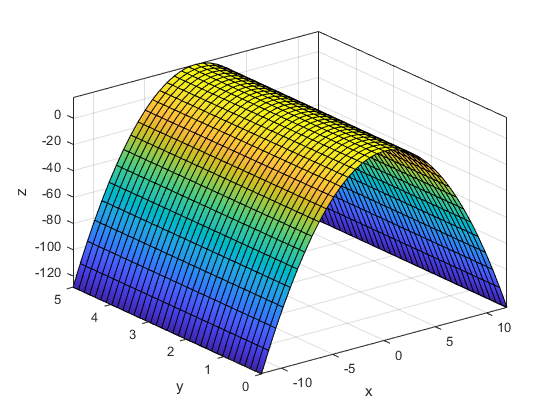

fsurf(r_st(1,1),r_st(1,2),r_st(1,3), [-12 12 0 5])   % or ezsurf(x, y, z, [0 2*pi 0 pi
%title('r(s, t) arbitrary surface [-10, 10]')
xlabel('x');
ylabel('y');
zlabel('z');
box on

% If we where to find the normal to a point on this fancy curve we would use partial derivatives
rs = diff(r_st, s)

$$rs = \left(\begin{array}{ccc} 1 & 0 & -2\,s \end{array}\right)$$

rt = diff(r_st, t)

$$rt = \left(\begin{array}{ccc} 0 & 1 & 0 \end{array}\right)$$


N = cross(rs, rt)

$$N = \left(\begin{array}{ccc} 2\,s & 0 & 1 \end{array}\right)$$


% Definiton of point
sp = -4.11765;
tp = 2.79412;

p = subs(r_st, [s, t], [sp, tp])

$$p = \left(\begin{array}{ccc} -\frac{82353}{20000} & \frac{69853}{25000} & -\frac{582016609}{400000000} \end{array}\right)$$


rsp = subs(rs, [s, t], [sp, tp])

$$rsp = \left(\begin{array}{ccc} 1 & 0 & \frac{82353}{10000} \end{array}\right)$$

rtp = subs(rt, [s, t], [sp, tp])

$$rtp = \left(\begin{array}{ccc} 0 & 1 & 0 \end{array}\right)$$


% Normal vector at point
Np = cross(rsp, rtp)

$$Np = \left(\begin{array}{ccc} -\frac{82353}{10000} & 0 & 1 \end{array}\right)$$

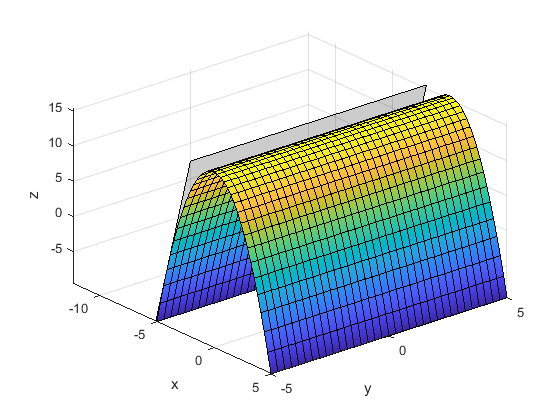


% Scaling of Normal vector (For visualization)
Np = 10*Np;



% Setup plot
fsurf(r_st(1,1),r_st(1,2),r_st(1,3)); hold on % OR ezmesh(r_st(1),r_st(2),r_st(3)
% Tangentline
f = @(x,y,z) Np(1)*(x-p(1)) + Np(2)*(y-p(2)) + Np(3)*(z-p(3));
fimplicit3(f, 'MeshDensity', 2, 'FaceColor','k',"FaceAlpha",0.2)
plot3(p(1), p(2), p(3), 'ro')
quiver3(p(1), p(2), p(3), Np(1), Np(2), Np(3), 0.1, 'color', 'r', 'ShowArrowHead', 'off', 'AutoScale', 'on', 'AutoScaleFactor', 0.1)
quiver3(p(1), p(2), p(3), -Np(1), -Np(2), -Np(3), 0.1, 'color', 'b', 'ShowArrowHead', 'off', 'AutoScale', 'on', 'AutoScaleFactor', 0.1)
xlabel('x'); ylabel('y'); zlabel('z');
view(50,34); hold off

% Frenet frame on a space curve

% Definiton of space curve
x_t = t;
y_t = t;
z_t = -t^2+15.5;
r_t = [x_t, y_t, z_t]

$$r\_t = \left(\begin{array}{ccc} t & t & \frac{31}{2}-t^{2} \end{array}\right)$$



% Definitions of functions
realdot = @(u, v) u*transpose(v);

% For computing Euclidean lengths of vectors
veclength = @(v) sqrt(realdot(v,v));

% Converts a vector to it's unit vector by dividing the vector by its length
unitvec = @(v) v/veclength(v);

% The frenet frame is a triple of vectors (T, N, B)
% T -> is the unit tangent vector at that point
% N -> the unit vector in the direction of the derivative of the unit tangent with respect to arclength
% B -> binormal B = T x N

% We calculate the Frenet frame for the twisted cubic
tcvel=diff(r_t)

$$tcvel = \left(\begin{array}{ccc} 1 & 1 & -2\,t \end{array}\right)$$

tctan=simplify(unitvec(tcvel))

$$tctan = \left(\begin{array}{ccc} \frac{\sqrt{2}}{2\,\sqrt{2\,t^{2}+1}} & \frac{\sqrt{2}}{2\,\sqrt{2\,t^{2}+1}} & -\frac{\sqrt{2}\,t}{\sqrt{2\,t^{2}+1}} \end{array}\right)$$

tcacc=diff(tcvel)

$$tcacc = \left(\begin{array}{ccc} 0 & 0 & -2 \end{array}\right)$$

% Because the acceleration a is not parallel to the unit normal N, 
% but the cross-product v × a of the velocity and the acceleration is parallel to the unit binormal B, 
% it is convenient to compute the unit binormal before the unit normal vector.

tccross=cross(tcvel,tcacc)

$$tccross = \left(\begin{array}{ccc} -2 & 2 & 0 \end{array}\right)$$

tcbin=simplify(unitvec(tccross))

$$tcbin = \left(\begin{array}{ccc} -\frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} & 0 \end{array}\right)$$


% Since T is perpendicuar to N 
% and B = T × N, the three unit vectors T, N, 
% and B are mutually perpendicular, and it follows that also N = B × T and T = N × B. 
% This gives the fastest way to compute N.

tcnorm = simplify(cross(tcbin, tctan))

$$tcnorm = \left(\begin{array}{ccc} -\frac{t}{\sqrt{2\,t^{2}+1}} & -\frac{t}{\sqrt{2\,t^{2}+1}} & -\frac{1}{\sqrt{2\,t^{2}+1}} \end{array}\right)$$

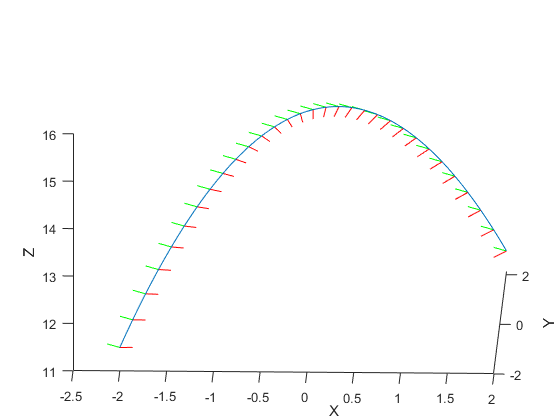

curveframeplot(r_t,'t',-2,2,30,.2)


syms s
tctube=r_t+ .2*cos(s)*tcnorm+.2*sin(s)*tcbin ;
pretty(tctube)

/     sqrt(2) sin(s)           sqrt(2) sin(s)       31    2        cos(s)      \
| t - -------------- - #1, t + -------------- - #1, -- - t  - ---------------- |
|           10                       10              2                  2      |
\                                                             5 sqrt(2 t  + 1) /

where

             t cos(s)
   #1 == ----------------
                   2
         5 sqrt(2 t  + 1)




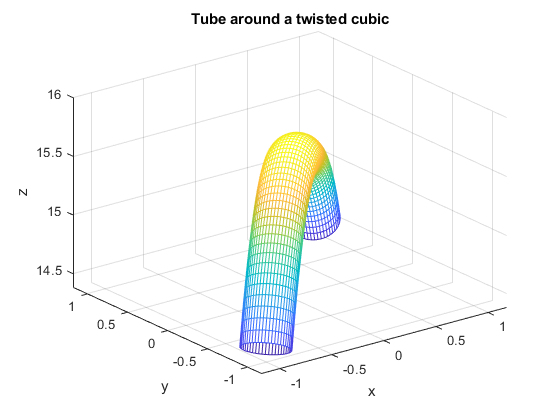

ezmesh(tctube(1),tctube(2),tctube(3),[0,2*pi,-1,1])
title('Tube around a twisted cubic')